# Surfaces defined by parametric functions

Finally, a more general representation of a surface involves expressing its coordinates in terms of two independent variables


$$x = f(u,v), y = g(u,v), z = h(u,v)$$


where u and v take values in some domain in 2D. For example, if we restrict $u \in [a,b]$ and $v \in [c,d]$ then the domain in the uv-plane is a rectangle. At each point in this rectangle, we determine the coordinates (x,y,z), and if we glue all of these points together then we define a parametric surface in the xyz-space. For example,


$$x = \sin u \cos v, y = \sin u \sin v, z = \cos u, u \in [0,\pi], v \in [0,2\pi]$$


defines a sphere of radius 1, centered at the origin. In order to visualize this in Matlab we first define a mesh grid in the uv-domain

u = linspace(0,10*pi,100)

u =          0    0.3173    0.6347    0.9520    1.2693    1.5867    1.9040    2.2213    2.5387    2.8560    3.1733    3.4907    3.8080    4.1253    4.4427    4.7600    5.0773    5.3947    5.7120    6.0293    6.3467    6.6640    6.9813    7.2986    7.6160    7.9333    8.2506    8.5680    8.8853    9.2026    9.5200    9.8373   10.1546   10.4720   10.7893   11.1066   11.4240   11.7413   12.0586   12.3760   12.6933   13.0106   13.3280   13.6453   13.9626   14.2800   14.5973   14.9146   15.2320   15.5493


v = linspace(0,10*pi,100)

v =          0    0.3173    0.6347    0.9520    1.2693    1.5867    1.9040    2.2213    2.5387    2.8560    3.1733    3.4907    3.8080    4.1253    4.4427    4.7600    5.0773    5.3947    5.7120    6.0293    6.3467    6.6640    6.9813    7.2986    7.6160    7.9333    8.2506    8.5680    8.8853    9.2026    9.5200    9.8373   10.1546   10.4720   10.7893   11.1066   11.4240   11.7413   12.0586   12.3760   12.6933   13.0106   13.3280   13.6453   13.9626   14.2800   14.5973   14.9146   15.2320   15.5493


[U,V] = meshgrid(u,v)

U =          0    0.3173    0.6347    0.9520    1.2693    1.5867    1.9040    2.2213    2.5387    2.8560    3.1733    3.4907    3.8080    4.1253    4.4427    4.7600    5.0773    5.3947    5.7120    6.0293    6.3467    6.6640    6.9813    7.2986    7.6160    7.9333    8.2506    8.5680    8.8853    9.2026    9.5200    9.8373   10.1546   10.4720   10.7893   11.1066   11.4240   11.7413   12.0586   12.3760   12.6933   13.0106   13.3280   13.6453   13.9626   14.2800   14.5973   14.9146   15.2320   15.5493
         0    0.3173    0.6347    0.9520    1.2693    1.5867    1.9040    2.2213    2.5387    2.8560    3.1733    3.4907    3.8080    4.1253    4.4427    4.7600    5.0773    5.3947    5.7120    6.0293    6.3467    6.6640    6.9813    7.2986    7.6160    7.9333    8.2506    8.5680    8.8853    9.2026    9.5200    9.8373   10.1546   10.4720   10.7893   11.1066   11.4240   11.7413   12.0586   12.3760   12.6933   13.0106   13.3280   13.6453   13.9626   14.2800   14.5973   14.9146   15.2320   15

V =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0

Now we define a function that defines the parametric equations for the sphere. You will find it at the end of this script, but we copy it here for clarity

**function [x,y,z] = sphereparam(u,v)**

**    x = sin(u) cos(v)**

**    y = sin(u) sin(v)**

**    z = cos(u)**

**end**

Now we can call the function, and then use **surf** to visualize the sphere.

[X,Y,Z] = sphereparam(U,V)

X =          0    0.3120    0.5929    0.8146    0.9549    0.9999    0.9450    0.7958    0.5671    0.2817   -0.0317   -0.3420   -0.6182   -0.8326   -0.9638   -0.9989   -0.9341   -0.7761   -0.5406   -0.2511    0.0634    0.3717    0.6428    0.8497    0.9718    0.9969    0.9224    0.7557    0.5137    0.2203   -0.0951   -0.4009   -0.6668   -0.8660   -0.9788   -0.9938   -0.9096   -0.7346   -0.4862   -0.1893    0.1266    0.4298    0.6901    0.8815    0.9848    0.9898    0.8960    0.7127    0.4582    0.1580
         0    0.2965    0.5633    0.7739    0.9072    0.9500    0.8978    0.7560    0.5387    0.2677   -0.0301   -0.3249   -0.5873   -0.7910   -0.9157   -0.9490   -0.8875   -0.7374   -0.5136   -0.2386    0.0603    0.3531    0.6107    0.8073    0.9233    0.9471    0.8763    0.7180    0.4880    0.2093   -0.0903   -0.3809   -0.6335   -0.8228   -0.9299   -0.9442   -0.8642   -0.6979   -0.4619   -0.1798    0.1203    0.4083    0.6556    0.8374    0.9356    0.9404    0.8513    0.6771    0.4353    0

Y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0974    0.1850    0.2542    0.2980    0.3120    0.2949    0.2483    0.1769    0.0879   -0.0099   -0.1067   -0.1929   -0.2598   -0.3008   -0.3117   -0.2915   -0.2422   -0.1687   -0.0784    0.0198    0.1160    0.2006    0.2651    0.3032    0.3111    0.2878    0.2358    0.1603    0.0687   -0.0297   -0.1251   -0.2081   -0.2702   -0.3054   -0.3101   -0.2838   -0.2292   -0.1517   -0.0591    0.0395    0.1341    0.2153    0.2750    0.3073    0.3089    0.2796    0.2224    0.1430    0

Z =     1.0000    0.9501    0.8053    0.5801    0.2969   -0.0159   -0.3271   -0.6056   -0.8237   -0.9595   -0.9995   -0.9397   -0.7861   -0.5539   -0.2665    0.0476    0.3569    0.6306    0.8413    0.9679    0.9980    0.9284    0.7660    0.5272    0.2358   -0.0792   -0.3863   -0.6549   -0.8580   -0.9754   -0.9955   -0.9161   -0.7453   -0.5000   -0.2048    0.1108    0.4154    0.6785    0.8738    0.9819    0.9920    0.9029    0.7237    0.4723    0.1736   -0.1423   -0.4441   -0.7015   -0.8888   -0.9874
    1.0000    0.9501    0.8053    0.5801    0.2969   -0.0159   -0.3271   -0.6056   -0.8237   -0.9595   -0.9995   -0.9397   -0.7861   -0.5539   -0.2665    0.0476    0.3569    0.6306    0.8413    0.9679    0.9980    0.9284    0.7660    0.5272    0.2358   -0.0792   -0.3863   -0.6549   -0.8580   -0.9754   -0.9955   -0.9161   -0.7453   -0.5000   -0.2048    0.1108    0.4154    0.6785    0.8738    0.9819    0.9920    0.9029    0.7237    0.4723    0.1736   -0.1423   -0.4441   -0.7015   -0.8888   -0

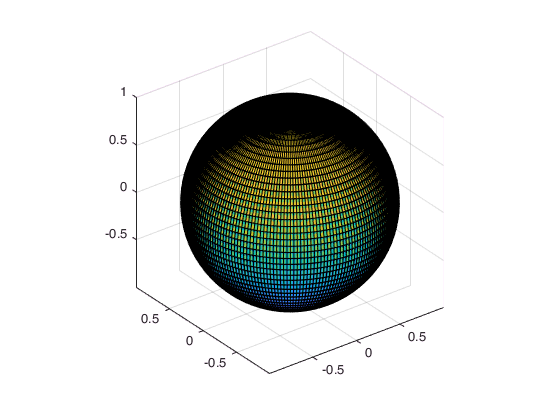

surf(X,Y,Z)
axis equal

**Exercise 1: **Consider the following parametric equations


$$x = (a + r \cos u) \cos v, y = (a+r\cos u) \sin v, z = r \sin u
$$


with r < a, and defined on the domain $u \in [0, 2\pi], v \in [0, 2\pi] $.

- Write a function that accepts u,v,a, and r as inputs, and returns x,y, and z.

- Visualize the surface for some different values of a and r.

- What features of the surface do the parameters r and a control?

 **Answer: **

When a = 0, the shape is a sphere with radius = r

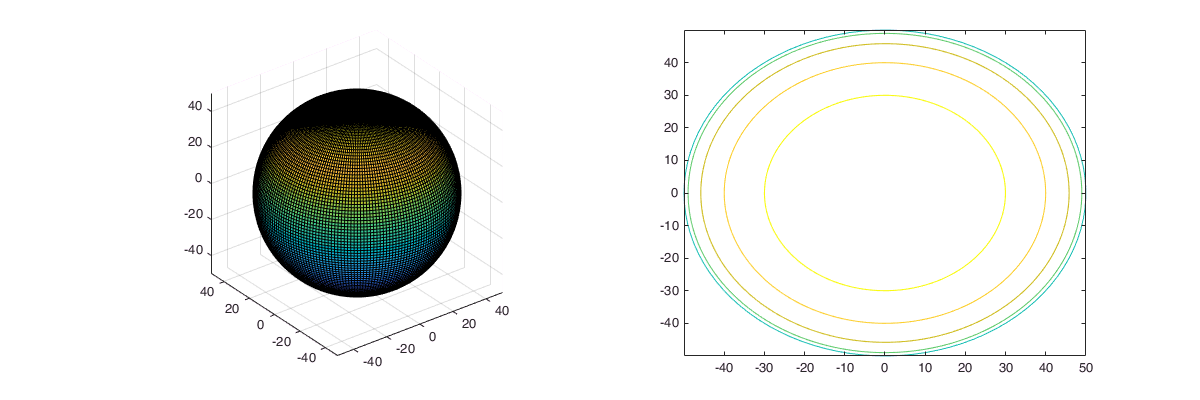

a = 0; r = 50;
[X, Y, Z] = shape(U, V, 0, 50);
figure('Position', [100, 100, 1200, 400]);
subplot(1,2,1);
surf(X,Y,Z)
axis equal
subplot(1,2,2);
contour(X,Y,Z)

 When **a** is present, the sphere begins to shrink vertically and there appears a hole in it. Appropriate values of** a** and **r** will make a donut! 

After trying different values of** r** with** a constant value of a**, my best guess is that** r = the radius of the donut - the radius of the center hole **and determines **how thick the donut would be**

Then I figured out that **a** decides **how wide the donut would be** in the** xy plane**. If you look at the figure below, **a **would be equal to **OA** where** O** is the donut's center

and **A** is the midpoint between the inner ring and the outer ring.

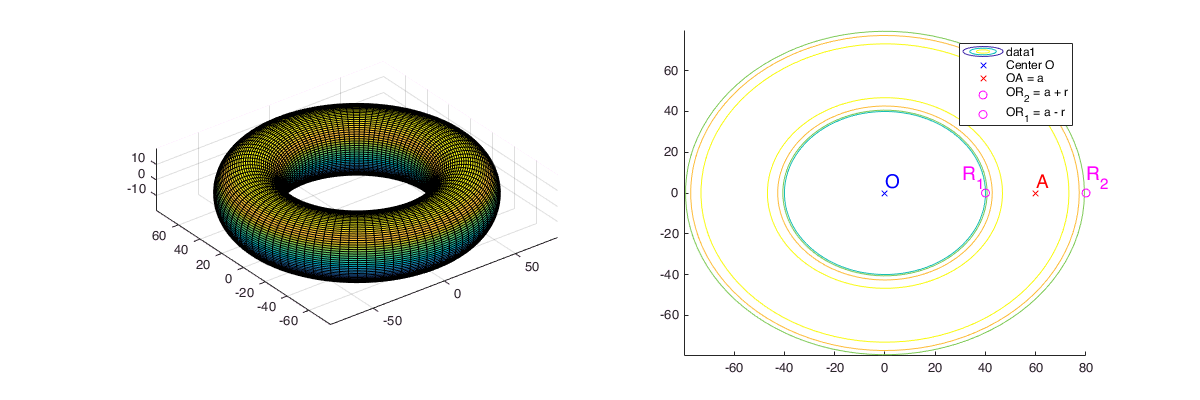

a = 60; r = 20;
[X, Y, Z] = shape(U, V, a, r);
figure('Position', [100, 100, 1200, 400]);

% Plot surf
subplot(1,2,1);
surf(X,Y,Z); axis equal

% Plot contour
subplot(1,2,2);
hold on
contour(X,Y,Z)

% Plot center O (0, 0)
plot(0,0,'bx', 'DisplayName','Center O');
text(0,0,'O','VerticalAlignment','bottom','Color','blue','FontSize',14);

% Plot a related point: A(60, 0)
plot(a,0,'rx', 'DisplayName','OA = a');
text(a,0,'A','VerticalAlignment','bottom','Color','red','FontSize',14);

% Plot r related points: R1(40, 0) & R2(80, 0)
plot(r+a,0,'mo', 'DisplayName','OR_2 = a + r');
text(r+a,0,'R_2','VerticalAlignment','bottom','Color','magenta','FontSize',14);

plot(a-r,0,'mo', 'DisplayName','OR_1 = a - r');
text(a-r,0,'R_1','VerticalAlignment','bottom','HorizontalAlignment','right','Color','magenta','FontSize',14);

legend('show');
hold off

**In the figure above:**

OA = a

R1R2 = 2r

OR1 = OA - AR1 = a - r

OR2 = OA + AR2 = a + r

Let's try different values of **a** and **r** and see if my guess is correct!

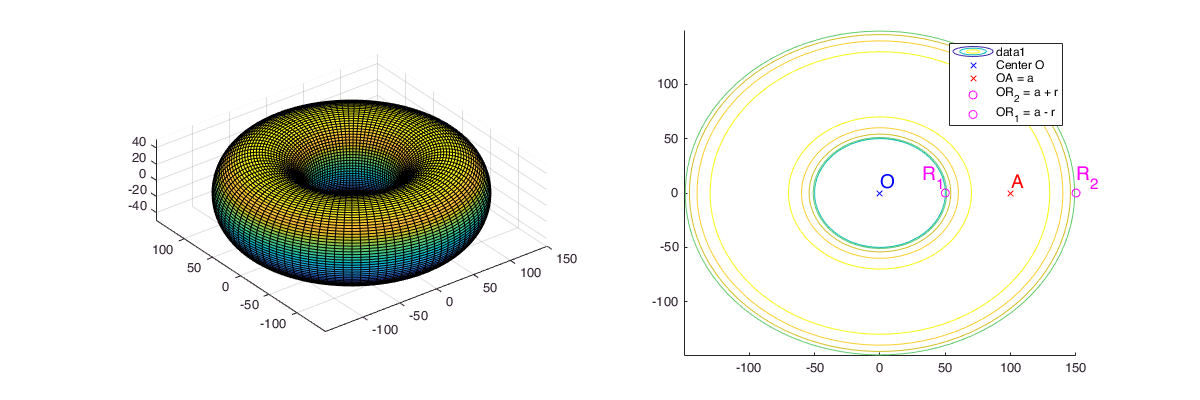

a = 100; r = 50;
[X, Y, Z] = shape(U, V, a, r);
figure('Position', [100, 100, 1200, 400]);

% Plot surf
subplot(1,2,1);
surf(X,Y,Z); axis equal

% Plot contour
subplot(1,2,2);
hold on
contour(X,Y,Z)

% Plot center O(0, 0)
plot(0,0,'bx', 'DisplayName','Center O');
text(0,0,'O','VerticalAlignment','bottom','Color','blue','FontSize',14);

% Plot a related point: A(100,0)
plot(a,0,'rx', 'DisplayName','OA = a');
text(a,0,'A','VerticalAlignment','bottom','Color','red','FontSize',14);

% Plot r related points: R1(50,0) & R2(50,0)
plot(r+a,0,'mo', 'DisplayName','OR_2 = a + r');
text(r+a,0,'R_2','VerticalAlignment','bottom','Color','magenta','FontSize',14);

plot(a-r,0,'mo', 'DisplayName','OR_1 = a - r');
text(a-r,0,'R_1','VerticalAlignment','bottom','HorizontalAlignment','right','Color','magenta','FontSize',14);

legend('show');
hold off

a = 100, r =50

A is at (100, 0)

R1 (50, 0)

R2 (50, 0)

p/s: I've validated that rings in the contour figure above are perfect circles, not ellipses by measuring the distance between O to the edges of the rings.

p/s 2: seems like bakers make donuts and donut holes using this function!

[X, Y, Z] = tamarind(U, V)

X =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1.2481    1

Y =     4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000
    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3.8003    3

Z =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0.3173    0

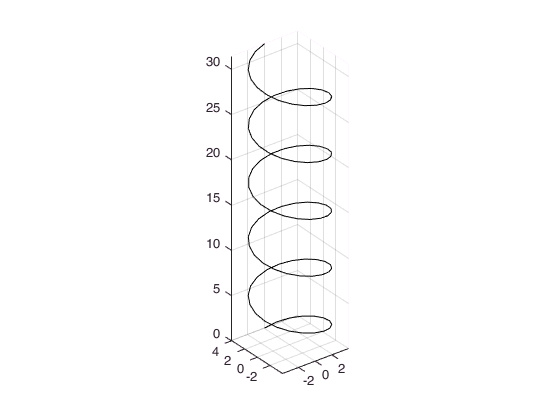

surf(X,Y,Z); axis equal

function [x,y,z] = sphereparam(u,v)
    x = sin(u).*cos(v);
    y = sin(u).*sin(v);
    z = cos(u);
end

function [x,y,z] = shape(u,v,a,r)
    x = (a + r.*cos(u)).*cos(v);
    y = (a + r.*cos(u)).*sin(v);
    z = r.*sin(u);
end

function [x,y,z] = tamarind(u,v)
    z = v;
    x = 4.*sin(v);
    y = 4.*cos(v);
end